class1 = 'TURMER';
class2 = 'LUSMEG';

filtBanks.fs44100 = gammatoneFilterBank([50 10000],64,44100);
filtBanks.fs48000 = gammatoneFilterBank([50 10000],64,48000);
filtBanks.fs96000 = gammatoneFilterBank([50 10000],64,96000);
filtBanks.fs88200 = gammatoneFilterBank([50 10000],64,88200);

[XTrain, YTrain] = createFeatureCells(TURMER_train40,LUSMEG_train40,class1,class2);
XTrainFs = vertcat(TURMER_trainFs40,LUSMEG_trainFs40);
[XTest, YTest] = createFeatureCells(TURMER_test40,LUSMEG_test40,class1,class2);
XTestFs = vertcat(TURMER_testFs40,LUSMEG_testFs40);

XTrainMrcgBase = cellfun(@(a,b) extractMrcg(a,b,filtBanks),XTrainBase5,fsTrain,"UniformOutput",false);

XTrainMrcgBaseNoD = cellfun(@(a) a(1:256,:),XTrainMrcgBase,"UniformOutput",false);

[XTrainMrcg,YTrainMrcg,XValMrcg,YValMrcg] = createValidationSplit(XTrainMrcgBaseNoD,YTrain,"Split",0.05);

XTestMrcgBase = cellfun(@(a,b) extractMrcg(a,b,filtBanks),XTestBase5,fsTest,"UniformOutput",false);

XTestMrcgBaseNoD = cellfun(@(a) a(1:256,:),XTestMrcgBase,"UniformOutput",false);

rnnMrcgEvalCell = {};

numObservations = numel(XTrainMrcg);
for i=1:numObservations
    sequence = XTrainMrcg{i};
    sequenceLengths(i) = size(sequence,2);
end
[sequenceLengths,idx] = sort(sequenceLengths);
XTrainMrcg = XTrainMrcg(idx);
YTrain = YTrain(idx);

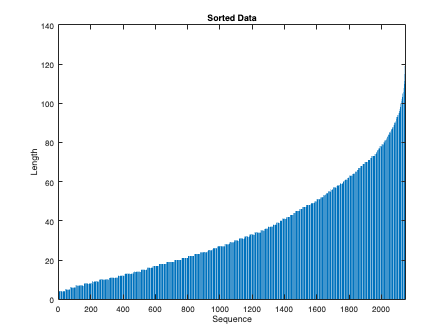

bar(sequenceLengths)
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

numObservationsTest = numel(XTestMrcgBaseNoD);
for i=1:numObservationsTest
    sequence = XTestMrcgBaseNoD{i};
    sequenceLengthsTest(i) = size(sequence,2);
end

[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTestMrcg = XTestMrcgBaseNoD(idx);
YTest = YTest(idx);

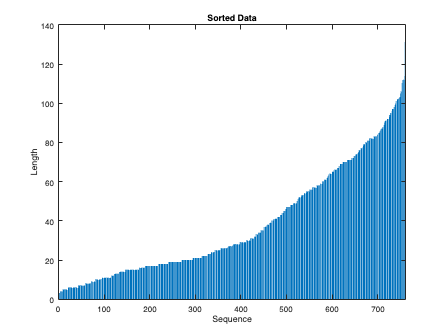

bar(sequenceLengthsTest)
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

## Model 2: RNN model 1

miniBatchSize = 100;
inputSize = size(XTrainMrcg{1},1);
numHiddenUnits = 100;
numClasses = 2;

layers1 = [
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,OutputMode="last")
    dropoutLayer(0.2)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

maxEpochs = 100;
options1 = trainingOptions("adam", ...
    "MiniBatchSize",miniBatchSize, ...
    "GradientThreshold",1, ...
    "Plots","training-progress", ...
    "SequenceLength","longest", ...
    "Shuffle","never", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XValMrcg,YValMrcg}, ...
    "Verbose",0);

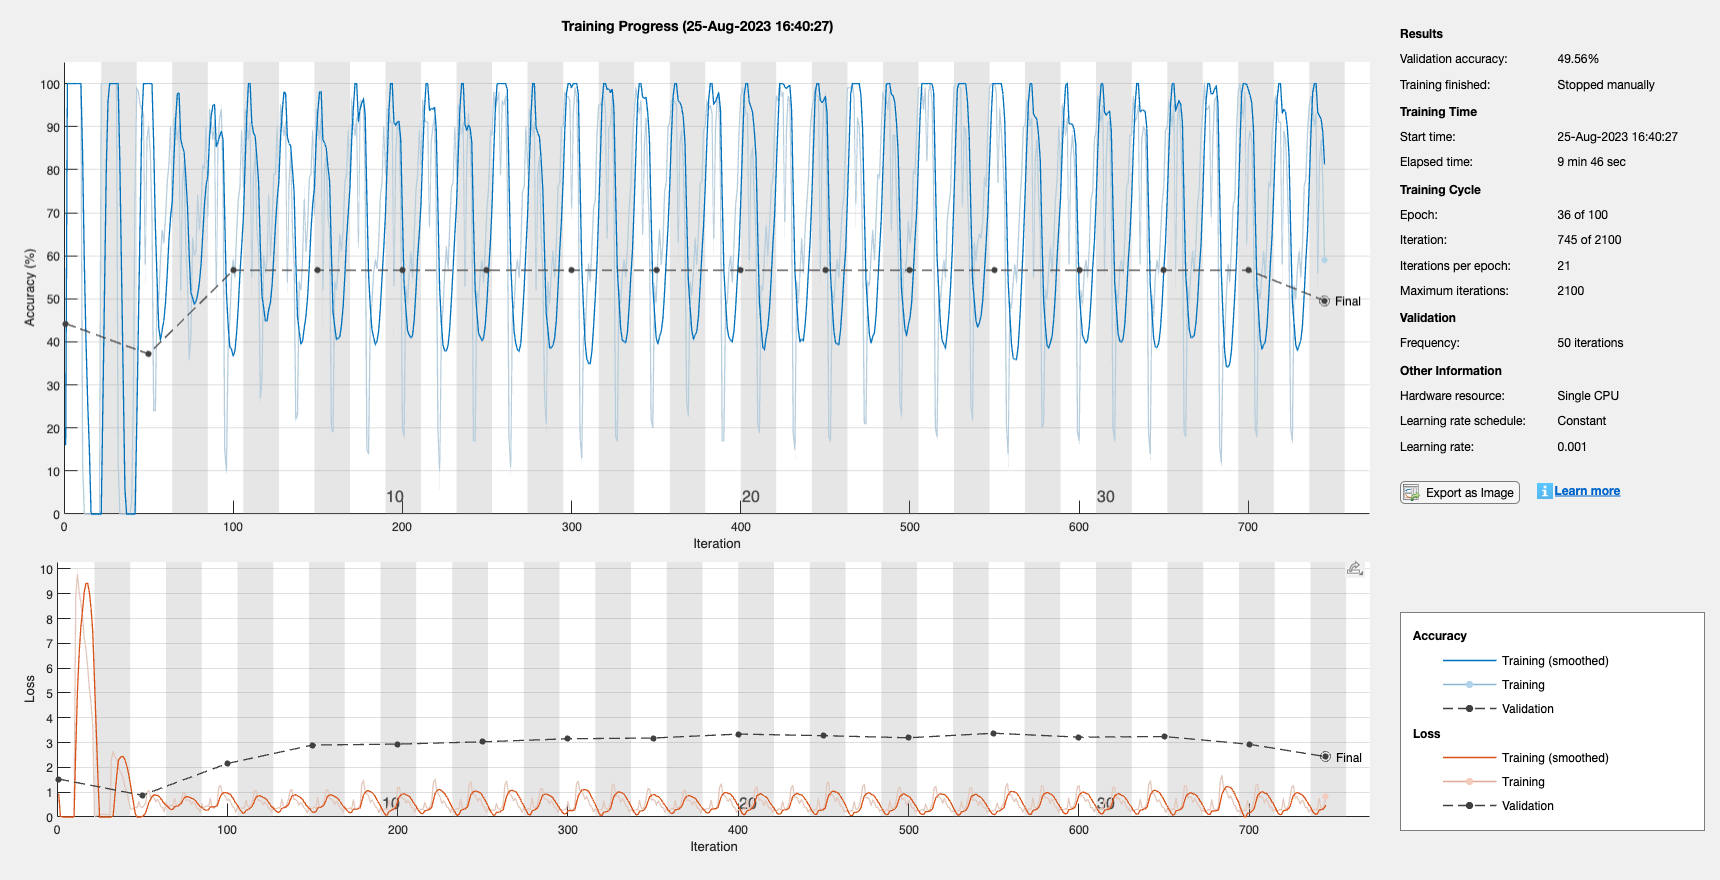

mrcgRnn1 = trainNetwork(XTrainMrcg,YTrainMrcg,layers1,options1);

30s per epoch

eval1 = generateEvaluationCell(mrcgRnn1,1,XTestMrcg,YTest,class1,miniBatchSize);
rnnMrcgEvalCell = [rnnMrcgEvalCell;eval1];

## Model 3: RNN model 2

miniBatchSize = 100;
inputSize = size(XTrainMrcg{1},1);
numHiddenUnits = 100;
numClasses = 2;
filterSize = 3;
numFilters = 32;

layers2 = [
    sequenceInputLayer(inputSize)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    layerNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    layerNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    globalAveragePooling1dLayer
    bilstmLayer(numHiddenUnits,OutputMode="last")
    dropoutLayer(0.5)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

maxEpochs = 100;
options2 = trainingOptions("adam", ...
    "MiniBatchSize",miniBatchSize, ...
    "GradientThreshold",1, ...
    "Plots","training-progress", ...
    "SequenceLength","longest", ...
    "Shuffle","never", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XValMrcg,YValMrcg}, ...
    "Verbose",0);

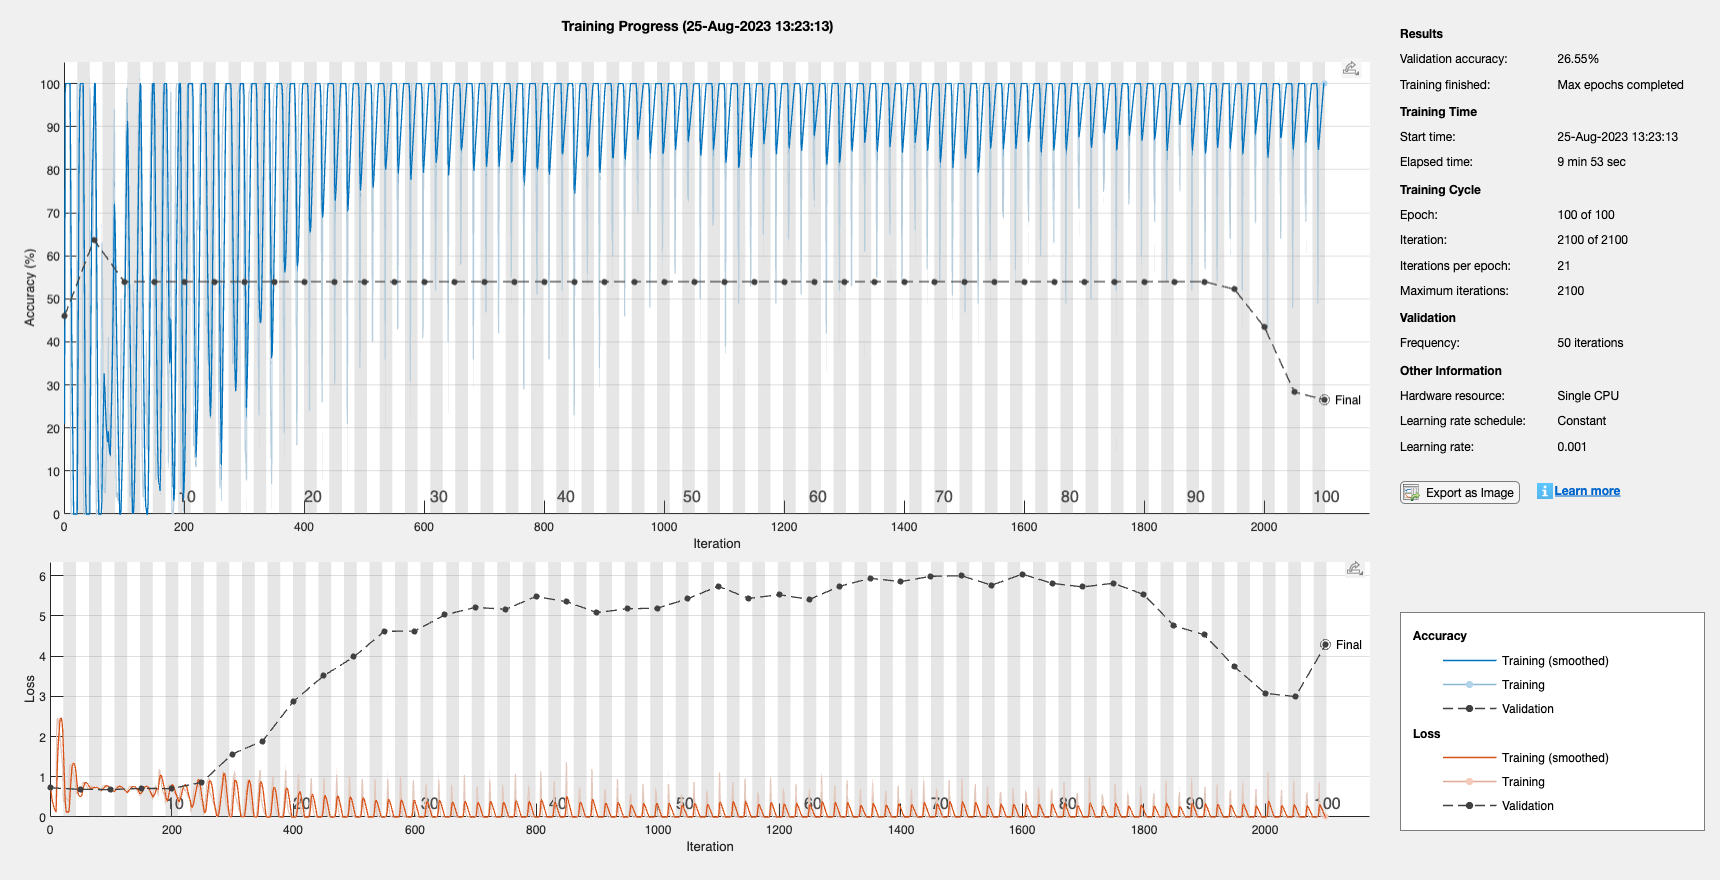

mrcgRnn2 = trainNetwork(XTrainMrcg,YTrainMrcg,layers2,options2);

9s per epoch

eval2 = generateEvaluationCell(mrcgRnn2,2,XTestMrcg,YTest,class1,miniBatchSize);
rnnMrcgEvalCell = [rnnMrcgEvalCell;eval2];

function mrcgFeature = extractMrcg(signal,fs,filtBanks)
gt = filtBanks.(sprintf('fs%d',fs));
audioOut = gt(signal);
mrcgFeature = mrcg(audioOut,fs);
del = audioDelta(mrcgFeature);
ddel = audioDelta(del);
mrcgFeature = [mrcgFeature;del;ddel];
end

function evalCell = generateEvaluationCell(model,archNumber,XTest,YTest,posClass,miniBatchSize)
[auc,accuracy,ROCX,ROCY] = evaluateRNN(model,XTest,YTest,posClass,miniBatchSize);
evalCell = {archNumber,auc,accuracy,ROCX,ROCY};
end